# Lecture et pré-traitement des données

clear variables;
close all;
clc;

## Structure de stockage des données dans Matlab

Remise en forme par rapport aux fichiers des expériences successives.

Quatre dimensions pour l'expérience :

- Index d'expérience (du sujet d'expérience) [à partir de 1]

- Numéro de synthé [de 1 à 12, y compris les essais] + 2bis. synthé via fader (indice{1}) ou via interpolation (indice{2})

- Numéro de paramètre [à partir de 1]

- Temps, de taille variable (et pour chaque valeur de temps, une valeur de paramètre)

Les 3 premières dimensions (y compris la 2bis qui n'est pas une dimension car taille fixe) sont stockées via un cell-array sur 4 indices qui a en fait la forme d'un pavé 3D.

La dernière dimension est stocké dans une matrice à 2 colonnes, de hauteur variable.

Nouvel indexage des expériences

Index +1 par rapport au C++ et aux noms des fichiers

Nouvel indexage des synthés

Qui doit commencer à partir de 1, car on ne va pas utiliser d'équivalent à std::map (qui permettaient de stocker les test dans des indices négatifs)

On décale de + le nombre de synthés de test (1 pour l'instant) puis +1 pour que les indices comment à zéro = +2 au total.

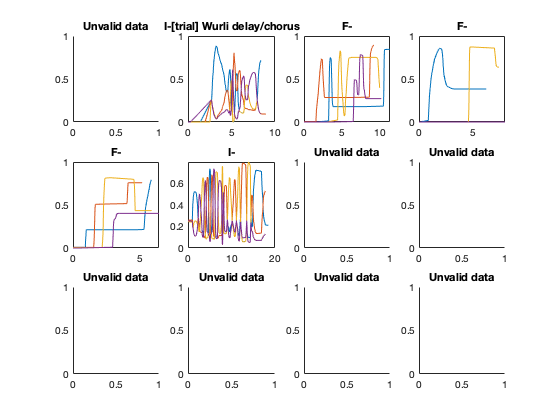

globalParams.parametersCount = 4; % 3rd cell-aray dimension

% fonction tres lente et tres inutile...
%slCharacterEncoding('UTF-8');

% fonction placees dans un sous-dossier
addpath('MatlabLib');

% 1 - - - Lecture du fichier d'infos - - -
% (pour connaitre le nombre d'experiences ?
% charger depuis les fichiers CSV et XML) general
xmlGeneralParams = xml2struct('A_OSC_Recorder_Experiment.xml');
% conversion vers des nombres pour tout ce qui est necessaire
globalParams.experimentsCount = str2num(xmlGeneralParams.experiments.count.Text); % dim 1
globalParams.synthsCount = str2num(xmlGeneralParams.experiments.synths.Attributes.total_count); % dim 2
globalParams.trialSynthsCount = str2num(xmlGeneralParams.experiments.synths.Attributes.trials_count);
% stockage des valeurs par d?faut dans un tableau.
% ligne = synth?, colonne = valeur du param par d?faut
globalParams.synthTargetValues = (-1) * ones(globalParams.synthsCount, globalParams.parametersCount);
for i2 = 1:globalParams.synthsCount
    % on suppose que les synth?s sont dans l'ordre dans le XML (pas de
    % v?rification de l'index)
    globalParams.synthNames{i2,1} = xmlGeneralParams.experiments.synths.synth{1,i2}.Attributes.name;
    % on suppose que les valeurs par d?faut des param?tres 
    % sont dans l'ordre !
    for i3 = 1:globalParams.parametersCount
        targetValue = str2double(xmlGeneralParams.experiments.synths.synth{1,i2}.parameters.parameter{1,i3}.Attributes.target_value);
        globalParams.synthTargetValues(i2, i3) = targetValue;
    end
end
clear xmlGeneralParams; clear targetValue

        % traduction ici du numero de synth
synthIdOffset = 1 + globalParams.trialSynthsCount;        

% 2 - - - Lecture des fichiers d'info XML de chaque experience - - -
for i = 1:globalParams.experimentsCount
    fileName = BuildInfoFileName(i-1);
    xmlExpeParams = xml2struct(fileName);
    experiments(i).presetsCount = str2num(xmlExpeParams.experiment.tested_presets.Attributes.count);
    % Ensuite on prevoit le stockage pour les experiences de tous les
    % synthes, avec ou sans faders. La moitie seulement sera utilise
    experiments(i).isFaderSynthRecorded = false(globalParams.synthsCount, 1);
    experiments(i).isInterpSynthRecorded = false(globalParams.synthsCount, 1);
    experiments(i).synthIndexesInAppearanceOrder = -1000 * ones(globalParams.synthsCount, 1);
    % on regarde quelles synths ont vraiment ete testes par ce sujet
    % (les entrees invalides sont considerees comme non-enregistrees)
    for j=1:experiments(i).presetsCount
        synthIdx = synthIdOffset + str2num(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.synth_id);
        isValid = strcmpi(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.is_valid, 'true');
        if isValid        
            % interpolation ou faders ?
            isFromInterpolation = strcmpi(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.from_interpolation, 'true');
            if (isFromInterpolation)
                experiments(i).isInterpSynthRecorded(synthIdx) = true;
            else
                experiments(i).isFaderSynthRecorded(synthIdx) = true;
            end
            % ordre d'apparence ?
            appearanceIndex = str2num(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.appearance_index);
            % tous les essais sont ? 1
            if (appearanceIndex < 0)
                appearanceIndex = 1;
            % les autres sont ? partir de 2
            else
                appearanceIndex = appearanceIndex + 2;
            end
            experiments(i).synthIndexesInAppearanceOrder(appearanceIndex) = synthIdx;
        end
    end
end
clear synthIdx; clear isValid; % temp vars
clear isFromInterpolation; clear appearanceIndex;
clear xmlExpeParams;


% 3 - - - Lecture des CSV des mesures durant l'experience - - -
expeData = cell(globalParams.experimentsCount, globalParams.synthsCount, 2, globalParams.parametersCount);
for i = 1:globalParams.experimentsCount
    fileName = BuildDataFileName(i-1);
    csvData = dlmread(fileName, ';', 1, 0); % to skip the header
    lastSynthId = -1000; % pour d?clencher un nouveau synth
    lastFromInterp = -1000; % sera un bool?en
    lastParamId = -1000; % pour d?clencher un nouveau param?tre        
    % lecture du fichier par blocs, chaque bloc = 1 matrice de 2 colonnes
    curSubMatrixFirstRow = 1;
    for csvMatrixRow = 1:size(csvData, 1)
        curSynthId = csvData(csvMatrixRow, 1) + synthIdOffset;
        curFromInterp = csvData(csvMatrixRow, 2);
        curParamId = csvData(csvMatrixRow, 3);
        % d?tection d'un nouveau bloc d?s qu'une des 3 colonnes change
        if (curSynthId ~= lastSynthId) || (curFromInterp ~= lastFromInterp) || (curParamId ~= lastParamId)
            % copie de la matrice par extraction de sous-matrice
            % (si au moins une ligne ? copier...)
            if (csvMatrixRow > curSubMatrixFirstRow)
                % (attention : on s'arr?te au rang juste avant)
                if (lastFromInterp == 0)
                    expeData{i, lastSynthId, 1, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow-1)), [4 5]);
                else
                    expeData{i, lastSynthId, 2, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow-1)), [4 5]);    
                end
            end
            % et lancement d'un nouveau bloc dans tous les cas
            lastFromInterp = curFromInterp;
            lastSynthId = curSynthId;
            lastParamId = curParamId;
            curSubMatrixFirstRow = csvMatrixRow;
        else
            % sinon, on ne fait rien ! copie sera faite ? un moment...
        end
    end
    % ? la fin, on sauvegarde le dernier bloc (qui ?tait en cours)
    % (attention : on s'arr?te au rang courant, de sortie de boucle)
    if (lastFromInterp == 0)
        expeData{i, lastSynthId, 1, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow)), [4 5]);
    else
        expeData{i, lastSynthId, 2, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow)), [4 5]);    
    end
end

clear i; clear j;
clear csvData; clear csvMatrixRow; clear fileName;
clear curSynthId; clear curFromInterp; clear curParamId;
clear lastSynthId; clear lastFromInterp; clear lastParamId;
clear curSubMatrixFirstRow;


% 4 - traitement préalable des données (conversion ms -> s)

% "Fermeture" des courbes : ajout de points en zéro et pour le dernier
% temps mesuré (pour tous les paramètres)
for i1 = 1:globalParams.experimentsCount
    for i2 = 1:globalParams.synthsCount
        % passe 1 : mesure des temps max pour fader et interp
        % AAAA FFAAAAIIIIIRRRRRRREE
        for i3 = 1:globalParams.parametersCount
            % fader (? refaire dans une 4? boucle
            if ( ~ isempty(expeData{i1, i2, 1, i3}) )
                expeData{i1, i2, 1, i3} = DuplicateFirstValueToTimeZero(expeData{i1, i2, 1, i3});
            end
            % interpolation
            if ( ~ isempty(expeData{i1, i2, 2, i3}) )
                expeData{i1, i2, 2, i3} = DuplicateFirstValueToTimeZero(expeData{i1, i2, 2, i3});
            end
        end
    end
end

% Conversion millisecondes -> secondes pour le temps
for i1 = 1:globalParams.experimentsCount
    for i2 = 1:globalParams.synthsCount
        for i3 = 1:globalParams.parametersCount
            if ( ~ isempty(expeData{i1, i2, 1, i3}) )
                rowsCount = size(expeData{i1, i2, 1, i3}, 1);
                conversionMatrix = [ (ones(rowsCount, 1)*0.001) ones(rowsCount, 1) ];
                % produit de Hadamard (multiplication terme à terme)
                expeData{i1, i2, 1, i3} = conversionMatrix .* expeData{i1, i2, 1, i3};
            end
            if ( ~ isempty(expeData{i1, i2, 2, i3}) )
                rowsCount = size(expeData{i1, i2, 2, i3}, 1);
                conversionMatrix = [ (ones(rowsCount, 1)*0.001) ones(rowsCount, 1) ];
                % produit de Hadamard (multiplication terme à terme)
                expeData{i1, i2, 2, i3} = conversionMatrix .* expeData{i1, i2, 2, i3};
            end
        end
    end
end



clear parameterCurve; clear rowsCount; clear conversionMatrix;
clear i1; clear i2; clear i3;

% Affichage d'une expérience en particulier
DisplayExperiment(globalParams, experiments, expeData, 2);

# Calcul des indicateurs de performance